# CAS Section 11.5

# Amelia Rotondo - 887925113

## Solve the DE: 

dy/dx = x(1-y) with y(1) = 0 

#### And Produce the Following Graphs in One Figure: 

% Initial Data
dydx = @(x,y) x*(1-y);
y = @(x)1-exp((1/2)*(1-x.^2));
y1 = 0; 
domain = [1 5];

% Produce all in 1 Figure: 
figure(1); clf; hold on; 
title('Amelia Rotondo, CAS 11.5 Numerical Solutions', 'FontSize',24);
legend('Location', 'best', 'FontSize',18);

## 1. Exact Solution y(x) = 1-exp(1/2*(1-x^2)) for x in [1,5]

% Finds the Exact Solution 
xx = 1:0.1:5;
yy = y(xx);
plot(xx, yy, 'y', 'DisplayName', 'Exact Solution', 'LineWidth',2);

## 2. Euler Solution for x in [1,5] with deltax = 0.1

% Euler Solution, deltax = 0.1
h = 0.1;
[x_e, y_e] = myEuler(dydx, domain, y1, h);
plot(x_e, y_e, 'g--', 'DisplayName', 'Euler: \Deltax = 0.1', 'LineWidth',2)

## 3. Euler Solution for x in [1,5] with deltax = 0.01

% Euler Solution, deltax = 0.1
h = 0.01;
[x_e, y_e] = myEuler(dydx, domain, y1, h);
plot(x_e, y_e, 'b--', 'DisplayName', 'Euler: \Deltax = 0.01', 'LineWidth',2)

## 4. Euler Solution for x in [1,5] with deltax = 0.001

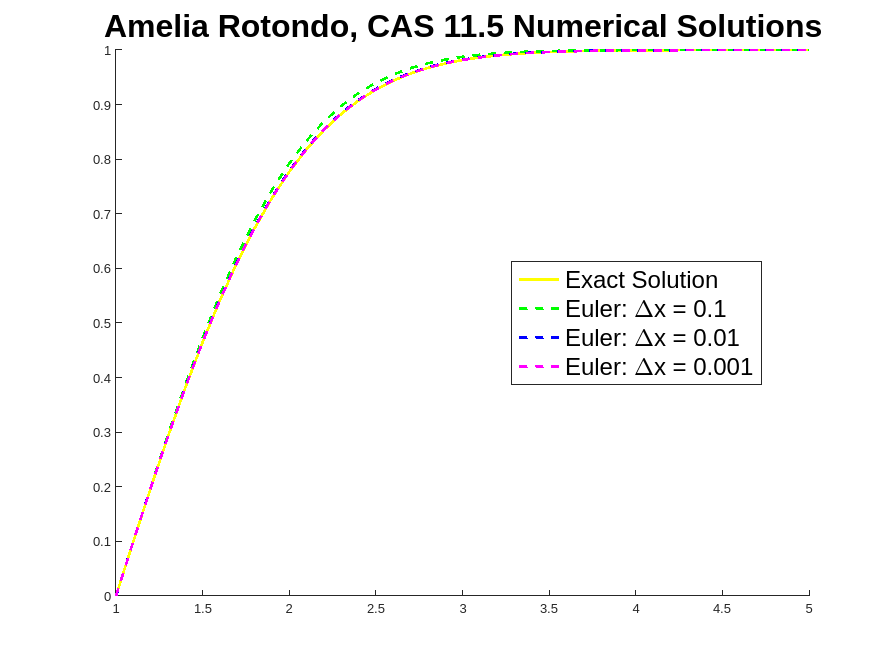

% Euler Solution, deltax = 0.1
h = 0.001;
[x_e, y_e] = myEuler(dydx, domain, y1, h);
plot(x_e, y_e, 'm--', 'DisplayName', 'Euler: \Deltax = 0.001', 'LineWidth',2)

## ETC: myEuler Function:

function [t, y] = myEuler(odefun, tspan, y0, h)
    % myEuler solves an ODE using the Euler method.
    % odefun - Function handle for the ODE (e.g., @(t, y) -1000*(y - sin(t)) + cos(t))
    % tspan  - 2-element vector with start and end times (e.g., [0 1])
    % y0     - Initial condition (e.g., 1)
    % h      - Step size (e.g., 0.001)

    % Time vector initialization
    t = tspan(1):h:tspan(2);
    if t(end) ~= tspan(2)  % Make sure the last time point is included
        t = [t tspan(2)];
    end
    N = length(t);  % Number of time points

    % Solution initialization
    y = zeros(1, N);
    y(1) = y0;

    % Euler's method loop
    for i = 1:N-1
        y(i+1) = y(i) + h * odefun(t(i), y(i));
    end
end